# Module 5: Design of Sampled Data Control Systems 

# Maria Júlia de Oliveira Vieira

GitHub: https://github.com/JuliaOli/Controle-II.git

## Embasamento teórico

The main difference is that the **lag compensator** adds negative phase to the system over the specified frequency range, while a **lead compensator** adds positive phase over the specified frequency. A **Bode plot** of a phase-**lag compensator** has the following form

A principal diferença é que o **lag compensator** adiciona fase negativa ao sistema na faixa de frequência especificada, enquanto um **lead compensator** adiciona fase positiva à frequência especificada.

Um lead compensator típico possui a seguinte função de transferência:


$$C\left(s\right)=K\frac{\tau s+1}{\alpha \tau s+1},\mathrm{onde},\alpha \pm <1$$


Onde $\frac{1}{\alpha }$ é a razão entre as frequências do break point do zero do pólo (limite). A magnitude do lead compensator é:


$$K=\frac{\sqrt{1+\omega^2 r^2 }}{\sqrt{1+\alpha^2 \omega^2 r^2 }}$$
 

E a fase contribuída pelo lead compensator é dada por:


$$\phi ={\mathrm{tan}}^{-1} \omega \tau -{\mathrm{tan}}^{-1} \alpha \omega \tau$$


Pode ser demonstrado que a frequência em que a fase é máxima é dada por:


$$\omega_{\mathrm{max}} =\frac{1}{\tau \sqrt{\alpha }}$$


The maximum phase corresponds to: 


$$\alpha =\left(\frac{1-\mathrm{sin}\left(\phi_{\mathrm{max}} \right)}{1+\mathrm{sin}\left(\phi_{\mathrm{max}} \right)}\right)$$


A magnitude de C (s) em $\omega_{\mathrm{max}}$:


$$\frac{K}{\sqrt{\alpha }}$$


## Lecture Note 6: Compensator Design Using Bode Plot

## Exemplo 1

num = 1;
den = [1 1 0];
G = tf(num,den);
H = 1;
% phase margin (PM) is at least 45 degrees
% error for a unit ramp input is â‰¤ 0.1.
% s â†’ 0, C(s) â†’ K
% Steady state error for unit ramp input is 1/K
% 1/K = 0.1
K = 10

K = 10


syms w_g
equ = 1 -100/(w_g^2 *(1+w_g^2)) == 0

$$equ = 1-\frac{100}{{w_{g}}^{2}\,\left({w_{g}}^{2}+1\right)}=0$$

equ_sol = solve(equ, w_g);
W_G = equ_sol(2) %deu certo aqui

$$W\_G = \frac{10\,\sqrt{2}}{\sqrt{\sqrt{401}+1}}$$


phase = -90 - atan(W_G)*180/pi

$$phase = -\frac{180\,\mathrm{atan}\left(\frac{10\,\sqrt{2}}{\sqrt{\sqrt{401}+1}}\right)}{\pi }-90$$

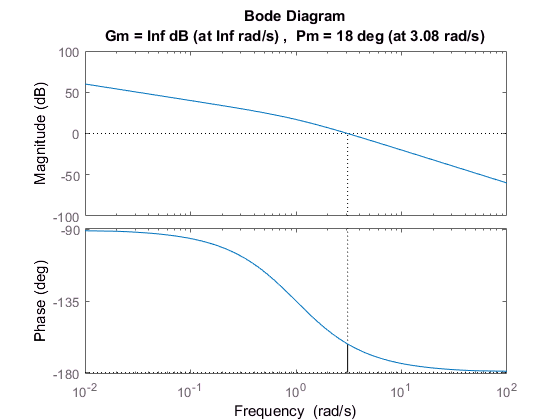

%margem de fase do sistema sem compensao para o valor de K dado. PM = 18
margin(G*K)

% Defining The maximum phase corresponds to sin(Ï†max)

PM = 18;

%the additional phase lead required to maintain PM=45 at  Ï‰ g = 3.1 rad/sec is 
phi_max = 45 - PM;
phi_max = phi_max + 10

phi_max = 37


alpha = (1-sin(phi_max*180/pi))/(1+sin(phi_max*180/pi))

alpha = 0.2578


% finding Ï„

w_max = 4.41;

tetazinho = 1/(w_max*(alpha)^(1/2))

tetazinho = 0.4466


% Lead Compensator

num = [tetazinho 1];
den = [tetazinho*alpha 1];

C = tf(num, den)


C =
 
  0.4466 s + 1
  ------------
  0.1151 s + 1
 
Continuous-time transfer function.



C = K*C


C =
 
  4.466 s + 10
  ------------
  0.1151 s + 1
 
Continuous-time transfer function.



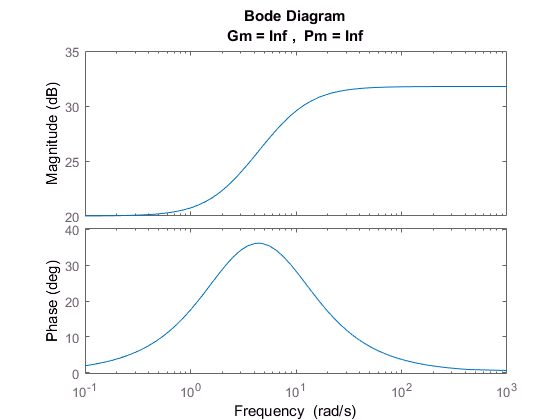

margin(C)

## Exemplo 2

%%
Ts = 0.2;
num = [0.0187 0.0175];
den = [1 -1.8187 0.8187];
G_z = tf(num, den, Ts)


G_z =
 
    0.0187 z + 0.0175
  ----------------------
  z^2 - 1.819 z + 0.8187
 
Sample time: 0.2 seconds
Discrete-time transfer function.



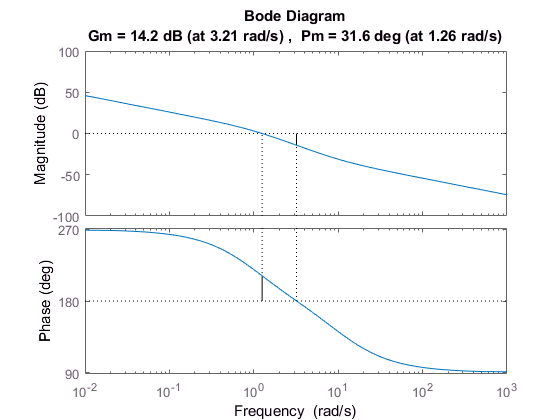


%The bi-linear transformation will transfer G z (z) into w-plane, as 
%We need first design a phase lead compensator so that PM of the compensated system is at
%least 50 0 with K v = 2 . The compensator in w-plane is

num = [-1/3000 - 29/300 1];
den = [1 1 0];
G_w = tf(num, den);
K = 2;
margin(G_w*K)

%%
PM = 31.6;

%the additional phase lead required to maintain PM=45 at  Ï‰ g = 3.1 rad/sec is 
phi_max = 50 - PM

phi_max = 18.4000

phi_max = phi_max + 11.6

phi_max = 30


alpha = (1-sin(phi_max*pi/180))/(1+sin(phi_max*pi/180))

alpha = 0.3333

%%
w_max = 1.75 %nem sei de onde veio

w_max = 1.7500


tetazinho = 1/(w_max*(alpha)^(1/2))

tetazinho = 0.9897


num = [tetazinho 1];
den = [tetazinho*alpha 1];

C = tf(num, den)


C =
 
  0.9897 s + 1
  ------------
  0.3299 s + 1
 
Continuous-time transfer function.



C = K*C


C =
 
  1.979 s + 2
  ------------
  0.3299 s + 1
 
Continuous-time transfer function.



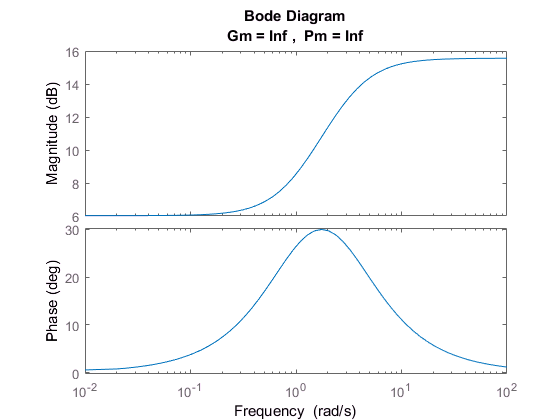

margin(C)

## Lecture Note 7: Lag Compensator Design

## Exemplo 1

%%
num = 1;
den = [0.5 1.5 1];
G = tf(num,den)


G =
 
           1
  -------------------
  0.5 s^2 + 1.5 s + 1
 
Continuous-time transfer function.



H = 1;

%Steady state error for unit step input is 1/(1 + lims?0 C(s)G(s)) = 
%1/( 1+ C(0)) = 1/( 1 + K?)
%Thus, 1/( 1 + K?) = 0.1, or, K = 9.

K_alpha = 9;
syms w_g

Mag = 0.715*w_g^2 - 1.5*w_g - 1.43 == 0;
Mag_sol = solve(Mag, w_g);
W_G = Mag_sol(2)

$$W\_G = \frac{\sqrt{2}\,\sqrt{31699}}{143}+\frac{150}{143}$$

W_G = 2.8;

%Novo K
K = 5.1;
alpha = 9/K;
tau = 10/W_G

tau = 3.5714


% Lead Compensator

num = [tau 1];
den = [tau*alpha 1];

C = tf(num, den)


C =
 
  3.571 s + 1
  -----------
  6.303 s + 1
 
Continuous-time transfer function.



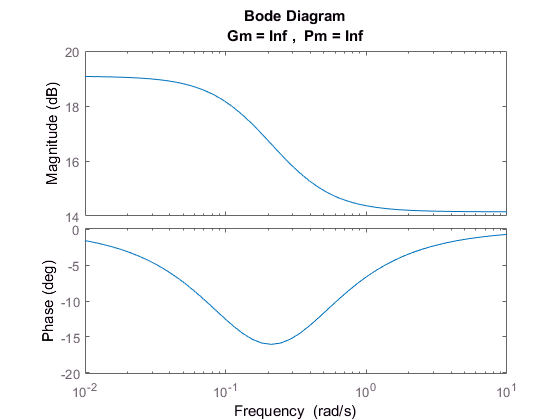


margin(C*9)

## Exemplo 2

%%
s=tf('s');
gc=1/(s*(1+0.1*s)*(1+0.2*s));
gz=c2d(gc,0.1,'z2h')


gz =
 
  0.005824 z^2 + 0.01629 z + 0.002753
  -----------------------------------
  z^3 - 1.974 z^2 + 1.198 z - 0.2231
 
Sample time: 0.1 seconds
Discrete-time transfer function.



aug=[0.1 1];

gwss = bilin(ss(gz),-1,'S_Tust',aug);
gw=tf(gwss)


gw =
 
  0.001756 s^3 - 0.06306 s^2 - 1.705 s + 45.27
  --------------------------------------------
     s^3 + 14.14 s^2 + 45.27 s - 6.032e-13
 
Continuous-time transfer function.



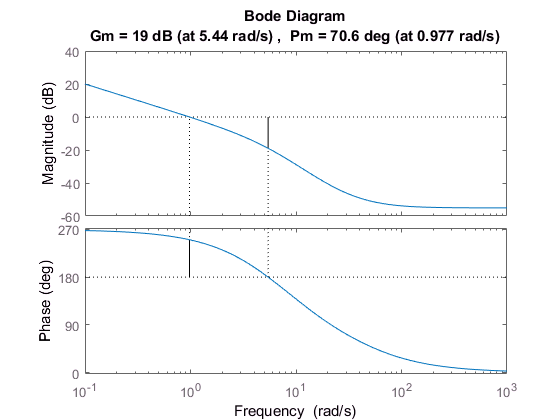


%Since Gw(0) = 1, Kα = 9 for 0.1 steady state error.
margin(gw)

## Lecture Note 8: Lag-lead Compensator

## Exemplo 1

Phase margin (PM) is at least 45 degrees, crossover frequency around 10 rad/sec and the velocity error constant Kv is 30.

%% Exemplo 1
num = 1;
den = [0.2 0.3 1 0];
G = tf(num,den)


G =
 
            1
  ---------------------
  0.2 s^3 + 0.3 s^2 + s
 
Continuous-time transfer function.



K = 30

K = 30

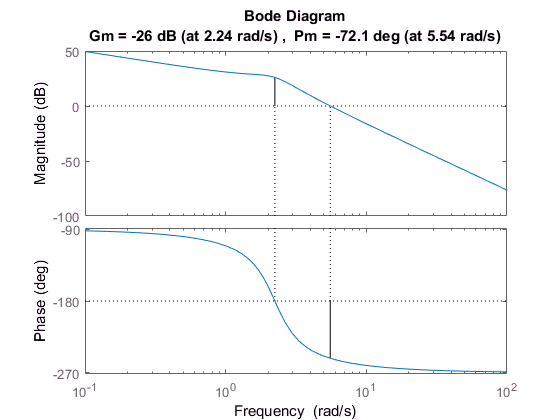

%G = G*K
margin(G*K)

**Dados apresentados na questão não batem com os produzidos**

**Since the PM of the uncompensated system with K is negative. We need a lead compensator to compensate for the negative PM and achieve the desired phase margin.

We design the lead part ﬁrst. From Figure 2, it is seen that at 10 rad/sec the phase angle of the system is −198o. Since the new ωg should be 10 rad/sec, the required additional phase at ωg, to maintain the speciﬁed PM, is 45−(180−198) = 63º. With safety margin 2º.***

phi_max = 63;
alpha = (1-sin(phi_max*pi/180))/(1+sin(phi_max*pi/180))

alpha = 0.0576

w_max = 10;
tau = 1/(w_max*(alpha)^(1/2))

tau = 0.4165


num = [tau 1];
den = [tau*alpha 1];
C_lead = tf(num, den)


C_lead =
 
  0.4165 s + 1
  -------------
  0.02401 s + 1
 
Continuous-time transfer function.



A introdução desse compensador aumentará a frequência de crossover de ganho, onde a característica da fase será diferente da designada.

 Resposta de frequência do sistema no Exemplo 1 com apenas um compensador de avanço.

**Novamente é apresentado resultados diferentes

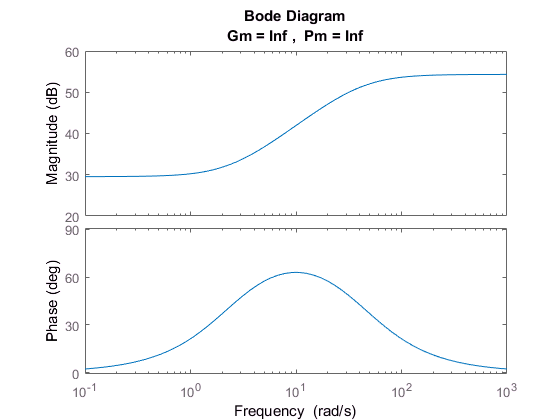

margin(K*C_lead)

Em altas frequências, a magnitude da parte do compensador de atraso é 1 / α.


$$20{\mathrm{log}}_{10} \alpha_1 =12\ldotp 6\Longrightarrow \alpha_1 =4\ldotp 27$$


%%
syms alpha_1
alpha_high = 20*log10(alpha_1) == 12.6;
alpha_solve = solve(alpha_high)

$$alpha\_solve = 10^{63/100}$$

alpha_solve = 4.2

alpha_solve = 4.2000

tau = 1/0.25

tau = 4

num = [tau 1];
den = [tau*alpha_solve 1];
C_comp = tf(num, den)


C_comp =
 
   4 s + 1
  ----------
  16.8 s + 1
 
Continuous-time transfer function.



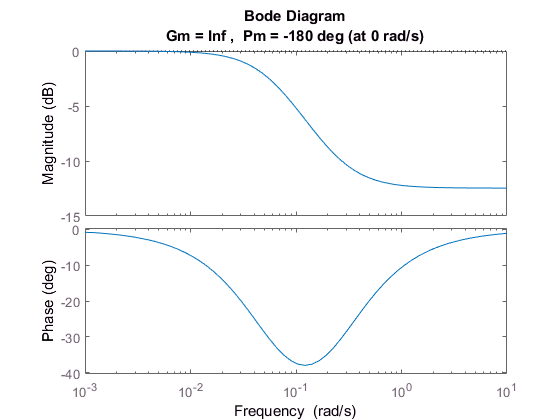

margin(C_comp)

C_final = K*C_comp*C_lead


C_final =
 
  49.98 s^2 + 132.5 s + 30
  ------------------------
  0.4033 s^2 + 16.82 s + 1
 
Continuous-time transfer function.



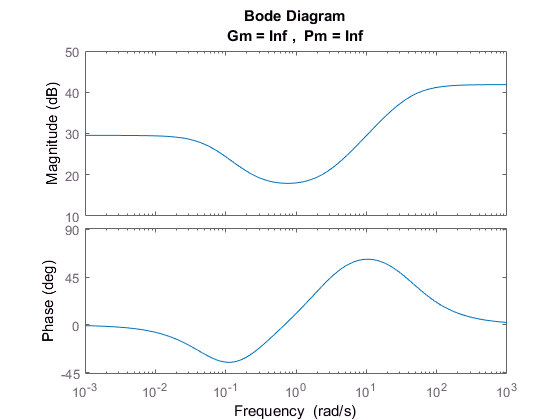

margin(C_final)

## Exemplo 2

%% 
s= tf('s'); 
gc=1/(s*(1+0.1*s)*(1+0.2*s)); 
gz=c2d(gc,0.1,'zoh')


gz =
 
  0.005824 z^2 + 0.01629 z + 0.002753
  -----------------------------------
  z^3 - 1.974 z^2 + 1.198 z - 0.2231
 
Sample time: 0.1 seconds
Discrete-time transfer function.



aug=[0.1,1]; 
gwss = bilin(ss(gz),-1,'S_Tust',aug);
gw=tf(gwss)


gw =
 
  0.001756 s^3 - 0.06306 s^2 - 1.705 s + 45.27
  --------------------------------------------
     s^3 + 14.14 s^2 + 45.27 s - 6.032e-13
 
Continuous-time transfer function.



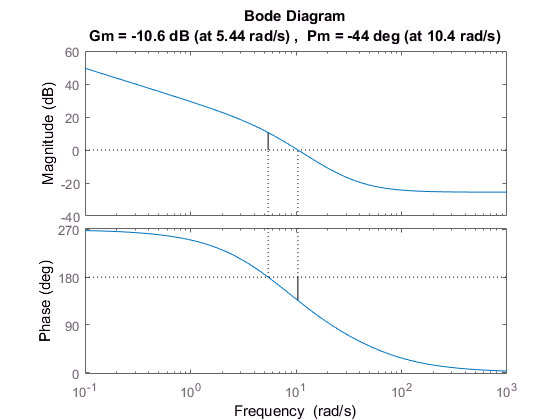

margin(30*gw)

phi_max = 66;
alpha_2 = (1-sin(phi_max*pi/180))/(1+sin(phi_max*pi/180))

alpha_2 = 0.0452

w_max = 10;
tau = 1/(w_max*(alpha_2)^(1/2))

tau = 0.4705

num = [tau 1];
den = [tau*alpha_2 1];
C_lead = tf(num, den)


C_lead =
 
  0.4705 s + 1
  -------------
  0.02126 s + 1
 
Continuous-time transfer function.



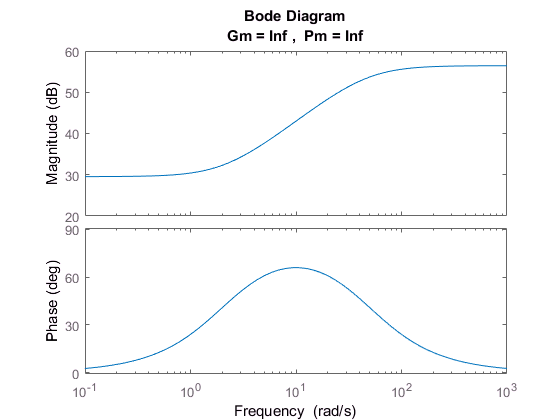

margin(30*C_lead)

syms alpha_1
alpha_high = 20*log10(alpha_1) == 14.2;
alpha_solve = solve(alpha_high)

$$alpha\_solve = 10^{71/100}$$

alpha_solve = 5.12;
tau = 1

tau = 1

num = [tau 1];
den = [tau*alpha_solve 1];
C_comp = tf(num, den)


C_comp =
 
    s + 1
  ----------
  5.12 s + 1
 
Continuous-time transfer function.



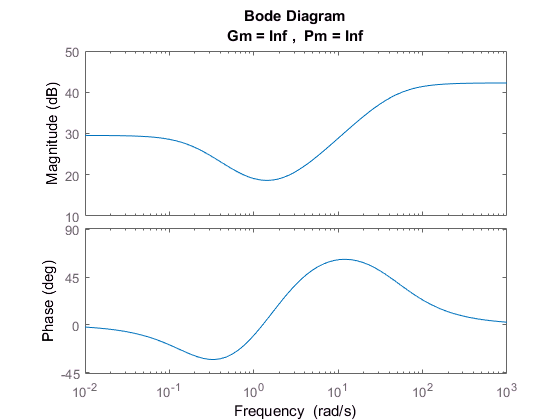

margin(30*C_lead*C_comp)